# 2PEM-100A

## `PRACTICE 3_1`

## `Sampling Rate Change and Data Filtering`

`More information:`

- [https://2pem100a.blogspot.com/](https://2pem100a.blogspot.com/)

`More examples:`

- [https://github.com/vasanza/Matlab_Code/tree/Electrical-Systems-Simulation](https://github.com/vasanza/Matlab_Code/tree/Electrical-Systems-Simulation)

- [https://github.com/avbazurt/Simulacion_Sistemas_Electricos](https://github.com/avbazurt/Simulacion_Sistemas_Electricos)

`Dataset:`

- [http://ieee-dataport.org/8630](http://ieee-dataport.org/8630)

Technical information

- Sampling frequency: 4Hz (250mSeg)

**1- Loading a .mat file**

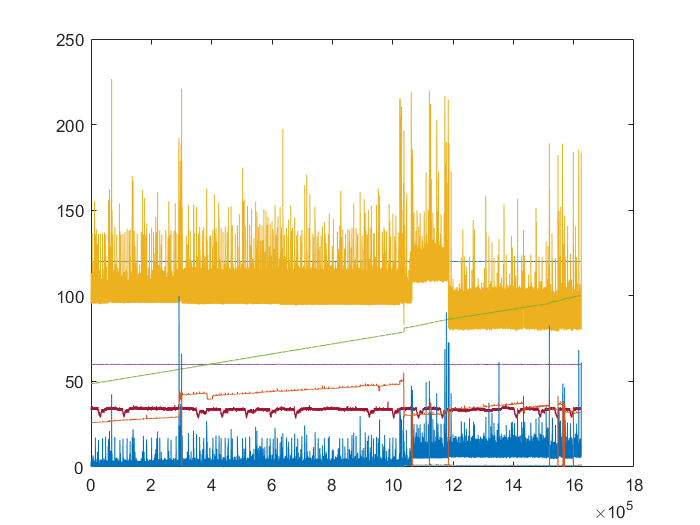

clear;clc;
path=fullfile('./dataset.mat');
data=load(path);%Load Raw Data
data=struct2cell(data);
data=data{1,1};%table
data=table2array(data(:,4:12));%array double
%Voltaje, Corriente, Potencia, Frecuencia, Energia, FP,Temp., CPU, RAM
plot(data);%datos originales

# **Example 1: Changing the sampling rate (4samples/sec -> 1sample/15min)**

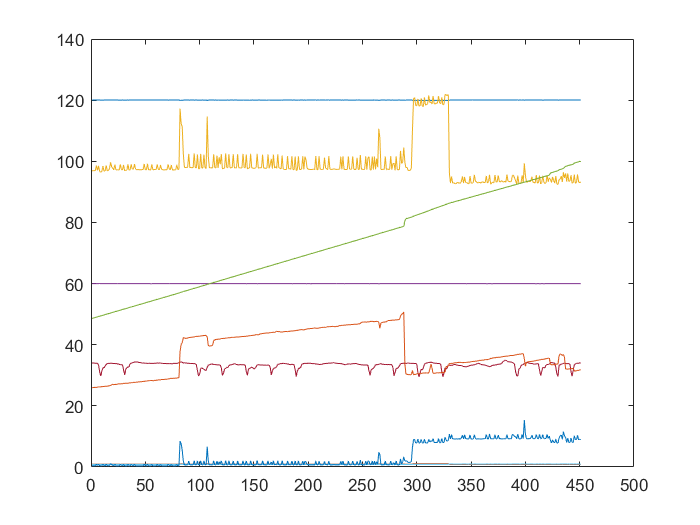

frecuencia=4;%Hz
minutos=15;%modificar la ventana temporal en minutos
ventana=frecuencia*60*minutos;%15min 3600 samples
datamean=[];datanomean=[];
for i = 1:ventana:length(data)-ventana
   datamean=[datamean;mean(data(i:i+ventana,:))];
   datanomean=[datanomean;data(i,:)];
end

plot(datamean);%datos en promedio cada 15min

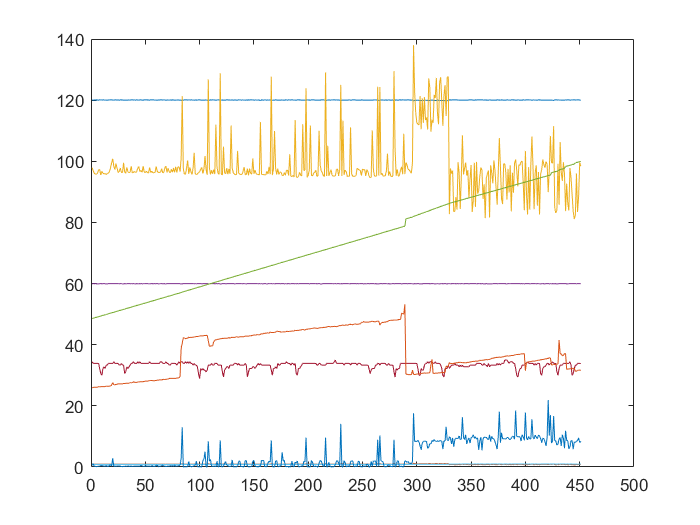

plot(datanomean);%datos SIN promedio cada 15min

# **Example 2: Saving a .mat file**

save('datamean.mat','datamean');

# **Example 3: Load file with 1sample / 15min sampling rate**

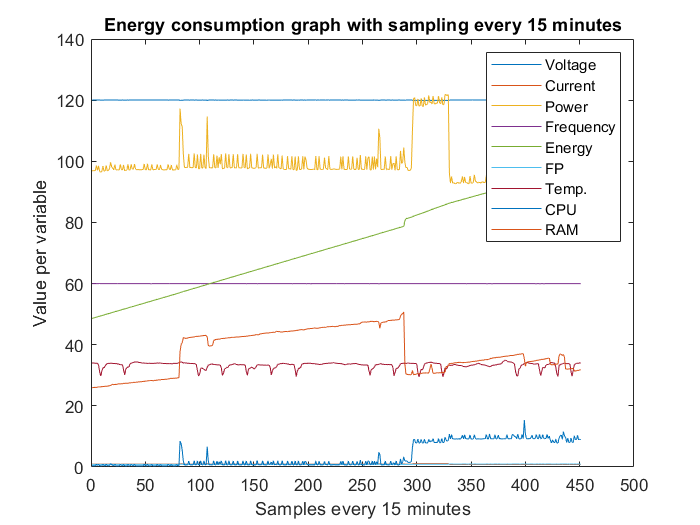

clear;%borra el worskpace
clc;%borra el comand windiw
path=fullfile('./datamean.mat');
data=load(path);
data=struct2cell(data);
data=data{1,1};%table
plot(data);%datos originales
title('Energy consumption graph with sampling every 15 minutes');
legend('Voltage','Current','Power','Frequency','Energy','FP','Temp.','CPU','RAM');

xlabel('Samples every 15 minutes');
ylabel('Value per variable');